% Initialisierung der Zustandsvariablen
R_0 = [0; 0; 0];  % Anfangsposition (Nullvektor)
V_0 = [0; 0; 0];  % Anfangsgeschwindigkeit (Nullvektor)

% Zustandsvektor x_k (6-dimensional: [x, y, z, vx, vy, vz])
x_k = [R_0; V_0];

% Zeitbereich auf eine Minute erweitern
t = linspace(0, 120, 240);

% Beschleunigung in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
A = [1 * cos(t/12); 0.5 * sin(t/12); 0.05 * ones(size(t/12))];

% Geschwindigkeit in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
V = cumtrapz(t/12, A, 2) + V_0;

% Position in x-, y- und z-Richtung in Abhängigkeit von der Zeit t
R_pos = R_0 + cumtrapz(t/12, V, 2) + 0.5 * cumtrapz(t/12, A, 2) .* t;

% Anzahl der Zeitschritte
N = length(t);

% Radarpositionen
pos_radar1 = [0, -10, 0];
pos_radar2 = [-50, 30, 0];
%x_k = [R_0; V_0];
% Zustandsvektor x_k (6-dimensional: [x, y, z, vx, vy, vz])
x_k = [R_pos(1,:); R_pos(2,:); R_pos(3,:); R_pos(1,:); R_pos(2,:); R_pos(3,:)];





% Prozessrauschkovarianzmatrix Q (Annahme: Prozessrauschen ist 0, da wir noch keine weiteren Informationen haben)
Q = zeros(6) * 0.01;

% Messrauschkovarianzmatrix R (Annahme: gleiche Varianzen für alle Beobachtungen)
standardabweichung = 0.1;
R = (standardabweichung^2) * eye(6);

% Zustandsübergangsmatrix F (Identity matrix as we assume constant velocity)
% Zeitschrittgröße
dt = t(2) - t(1);

% Zustandsübergangsmatrix F
F = [1 0 0 0 0 0;
    0 1 0 0 0 0;
    0 0 1 0 0 0;
    0 0 0 0 0 0;
    0 0 0 0 0 0;
    0 0 0 0 0 1]; 

% F = [eye(3), eye(3) * dt;
%      zeros(3), eye(3)];

% Schätzung der Anfangsvarianz des Zustandsvektors (Annahme: großer Wert, da wir wenig über den Anfangszustand wissen)
P = 1000 * eye(6);

messungen = [];
% EKF-Schätzung
for k = 2:N
    % Vorhersage
    x_k_pred = F * x_k(:, k-1);
    P_pred = F * P * F' + Q;
    
    % Update (Kalman Gain)
    H = create_observation_matrix(x_k_pred, pos_radar1, pos_radar2);
    K = P_pred * H' * inv(H * P_pred * H' + R);
    
    % Messungen
    %z_k = [calculate_observations(x_k(1:3, k), pos_radar1); calculate_observations(x_k(1:3, k), pos_radar2)];
    %x_k_mess = messungen_anpassen(x_k, pos_radar1,pos_radar2)
    z_k = [calculate_observations(x_k(:, k), pos_radar1); calculate_observations(x_k(:, k), pos_radar2)];
    
    messungen = [messungen, z_k];
    % Update der Zustandsschätzung und Fehlerkovarianz
    x_k(:, k) = x_k_pred + K * (z_k - [calculate_observations(x_k_pred, pos_radar1); calculate_observations(x_k_pred, pos_radar2)]);
    P = (eye(6) - K * H) * P_pred;
end

% Geschätzte Position des Helikopters
estimated_position = x_k(1:3, :)

estimated_position =          0    0.0223    0.0019    0.0601    0.0886    0.1462    0.2240    0.3195    0.4319    0.5605    0.7035    0.8574    1.0168    1.1765    1.3341    1.4902    1.6460    1.8025    1.9602    2.1190    2.2786    2.4384    2.5977    2.7557    2.9116    3.0646    3.2140    3.3588    3.4986    3.6325    3.7602    3.8811    3.9948    4.1010    4.1995    4.2900    4.3724    4.4465    4.5124    4.5700    4.6193    4.6604    4.6933    4.7180    4.7348    4.7435    4.7444    4.7376    4.7231    4.7010
         0    0.0040   -0.0480   -0.0305   -0.0500   -0.0473   -0.0293    0.0021    0.0462    0.1027    0.1698    0.2436    0.3177    0.3856    0.4446    0.4953    0.5396    0.5794    0.6158    0.6495    0.6810    0.7102    0.7370    0.7612    0.7825    0.8006    0.8151    0.8258    0.8324    0.8346    0.8324    0.8256    0.8142    0.7983    0.7780    0.7533    0.7246    0.6919    0.6557    0.6162    0.5737    0.5286    0.4811    0.4317    0.3808    0.3286    0.2756    0.22

% Funktion zur Berechnung der Beobachtungen (Messmodell)

messungen    

messungen =    10.0001   10.0010   10.0037   10.0091   10.0185   10.0332   10.0546   10.0843   10.1238   10.1748   10.2388   10.3173   10.4118   10.5236   10.6540   10.8038   10.9740   11.1650   11.3771   11.6105   11.8649   12.1400   12.4352   12.7496   13.0824   13.4324   13.7985   14.1793   14.5734   14.9796   15.3962   15.8220   16.2553   16.6949   17.1393   17.5870   18.0369   18.4875   18.9377   19.3863   19.8321   20.2742   20.7116   21.1434   21.5687   21.9869   22.3972   22.7991   23.1921   23.5758
   89.9348   89.7396   89.4150   88.9625   88.3845   87.6839   86.8650   85.9332   84.8952   83.7589   82.5336   81.2301   79.8600   78.4362   76.9723   75.4823   73.9805   72.4807   70.9964   69.5402   68.1236   66.7569   65.4487   64.2066   63.0365   61.9429   60.9293   59.9977   59.1494   58.3848   57.7033   57.1043   56.5861   56.1472   55.7857   55.4994   55.2862   55.1439   55.0704   55.0634   55.1210   55.2412   55.4221   55.6620   55.9592   56.3123   56.7197   57.1803   57.6

x_k_new_arr = [];
for i=1:length(messungen(1,:))
    x_k_new1 = x_k(1,i) - pos_radar1(1);
    x_k_new2 = x_k(1,i) - pos_radar1(2);
    x_k_new3 = x_k(1,i) - pos_radar1(3);
    x_k_new4 = x_k(1,i) - pos_radar2(1);
    x_k_new5 = x_k(1,i) - pos_radar2(2);
    x_k_new6 = x_k(1,i) - pos_radar2(3);
    x_k_new_arr = [x_k_new_arr; x_k_new1,x_k_new2,x_k_new3, x_k_new4,x_k_new5,x_k_new6];

end
transpose(x_k_new_arr)

ans =          0    0.0223    0.0019    0.0601    0.0886    0.1462    0.2240    0.3195    0.4319    0.5605    0.7035    0.8574    1.0168    1.1765    1.3341    1.4902    1.6460    1.8025    1.9602    2.1190    2.2786    2.4384    2.5977    2.7557    2.9116    3.0646    3.2140    3.3588    3.4986    3.6325    3.7602    3.8811    3.9948    4.1010    4.1995    4.2900    4.3724    4.4465    4.5124    4.5700    4.6193    4.6604    4.6933    4.7180    4.7348    4.7435    4.7444    4.7376    4.7231    4.7010
   10.0000   10.0223   10.0019   10.0601   10.0886   10.1462   10.2240   10.3195   10.4319   10.5605   10.7035   10.8574   11.0168   11.1765   11.3341   11.4902   11.6460   11.8025   11.9602   12.1190   12.2786   12.4384   12.5977   12.7557   12.9116   13.0646   13.2140   13.3588   13.4986   13.6325   13.7602   13.8811   13.9948   14.1010   14.1995   14.2900   14.3724   14.4465   14.5124   14.5700   14.6193   14.6604   14.6933   14.7180   14.7348   14.7435   14.7444   14.7376   14.7231   

messungen_kartesisch = get_kartesische_Koordianten(messungen)

messungen_kartesisch =     0.0114    0.0455    0.1021    0.1812    0.2824    0.4055    0.5499    0.7152    0.9008    1.1061    1.3304    1.5730    1.8330    2.1094    2.4015    2.7080    3.0281    3.3605    3.7041    4.0577    4.4199    4.7896    5.1654    5.5459    5.9297    6.3154    6.7015    7.0866    7.4692    7.8479    8.2211    8.5873    8.9450    9.2929    9.6293    9.9528   10.2620   10.5555   10.8318   11.0897   11.3277   11.5446   11.7392   11.9102   12.0566   12.1771   12.2708   12.3366   12.3737   12.3812
   10.0001   10.0009   10.0031   10.0074   10.0145   10.0249   10.0395   10.0589   10.0836   10.1143   10.1517   10.1963   10.2487   10.3094   10.3790   10.4579   10.5466   10.6456   10.7553   10.8760   11.0080   11.1518   11.3076   11.4756   11.6560   11.8490   12.0547   12.2732   12.5047   12.7490   13.0061   13.2761   13.5587   13.8539   14.1614   14.4811   14.8126   15.1557   15.5099   15.8751   16.2506   16.6361   17.0310   17.4349   17.8472   18.2672   18.6945   19.

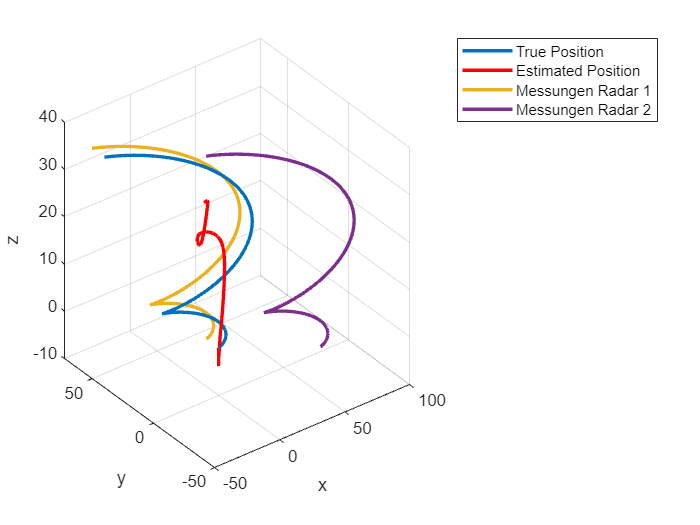

% Plot der geschätzten Position in 3D-Raum
figure(1);
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot3(estimated_position(1, :), estimated_position(2, :), estimated_position(3, :), 'r', 'LineWidth', 2);
plot3(messungen_kartesisch(1, :), messungen_kartesisch(2, :), messungen_kartesisch(3, :), 'LineWidth', 2);
plot3(messungen_kartesisch(4, :), messungen_kartesisch(5, :), messungen_kartesisch(6, :), 'LineWidth', 2);
hold off;
xlabel('x');
ylabel('y');
zlabel('z');
grid on;
legend('True Position', 'Estimated Position', 'Messungen Radar 1', 'Messungen Radar 2');

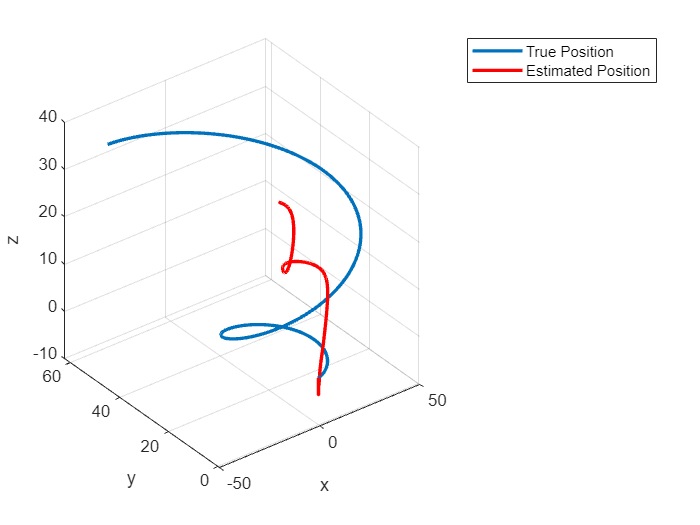



% Plot der geschätzten Position in 3D-Raum
figure(1);
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
hold on;
plot3(estimated_position(1, :), estimated_position(2, :), estimated_position(3, :), 'r', 'LineWidth', 2);

hold off;
xlabel('x');
ylabel('y');
zlabel('z');
grid on;
legend('True Position', 'Estimated Position');

function obs = calculate_observations(x_k, pos_radar)
    
    dist_matrix_radar1 = [];
    phi_radar1 = [];
    theta_radar1 = [];


    R_transposed = transpose(x_k);
    for i=1:length(R_transposed(:,1))
        dist_radar1 = norm(R_transposed(1:3) - pos_radar);  % Berechnet den Abstand zwischen der i-ten Zeile von R_transposed und pos_radar
        dist_matrix_radar1 = [dist_matrix_radar1; dist_radar1]; 
        % Berechnung des Elevationswinkels (phi) für Radar 1
        delta_z = R_transposed(3) - pos_radar(3);
        rho = sqrt((R_transposed(1) - pos_radar(1))^2 + (R_transposed(2) - pos_radar(2))^2 + delta_z^2);
        phi_radar1 = [phi_radar1;rad2deg(acos(delta_z/rho))];  % Fügt den Winkel zu phi_radar1 hinzu
        
        % Berechnung des Azimutwinkels (theta) für Radar 1
        delta_x = R_transposed(1) - pos_radar(1);
        delta_y = R_transposed(2) - pos_radar(2);
        theta_radar1 = [theta_radar1; rad2deg(atan2(delta_y, delta_x))];  % Fügt den Winkel zu theta_radar1 hinzu
    end 



    polar_koordinaten_radar1 = [dist_matrix_radar1, theta_radar1, phi_radar1];
    
    obs = transpose(polar_koordinaten_radar1);

end

function messungen = messungen_anpassen(x_k, pos_radar1, pos_radar2)

    x_k_new_arr = [];
    for i=1:length(x_k(1,:))
        x_k_new1 = x_k(1,i) - pos_radar1(1);
        x_k_new2 = x_k(1,i) - pos_radar1(2);
        x_k_new3 = x_k(1,i) - pos_radar1(3);
        x_k_new4 = x_k(1,i) - pos_radar2(1);
        x_k_new5 = x_k(1,i) - pos_radar2(2);
        x_k_new6 = x_k(1,i) - pos_radar2(3);
        x_k_new_arr = [x_k_new_arr; x_k_new1,x_k_new2,x_k_new3, x_k_new4,x_k_new5,x_k_new6];
    
    end
    messungen = transpose(x_k_new_arr);
end



function H = create_observation_matrix(x_k, pos_radar1, pos_radar2)
    H = zeros(6, 6);
    H(1:3, 1:3) = eye(3);
    H(4:6, 4:6) = eye(3);

    obs_radar1 = calculate_observations(x_k, pos_radar1);
    obs_radar2 = calculate_observations(x_k, pos_radar2);

    % Beobachtung 1 (Abstand zu pos_radar1)
    dxyz = x_k(1:3, 1)' - pos_radar1;
    H(1, 1:3) = dxyz / obs_radar1(1);

    % Beobachtung 2 (Azimutwinkel zu pos_radar1)
    dxy = dxyz(1:2);
    H(2, 1:2) = [-dxy(2), dxy(1)] / norm(dxy)^2;

    % Beobachtung 3 (Elevationswinkel zu pos_radar1)
    H(3, 1:3) = [-dxy(1)*dxyz(3), -dxy(2)*dxyz(3), norm(dxy)^2] / (obs_radar1(3) * norm(dxyz)^3);

    % Beobachtung 4 (Abstand zu pos_radar2)
    dxyz = x_k(1:3, 1)' - pos_radar2;
    H(4, 1:3) = dxyz / obs_radar2(1);

    % Beobachtung 5 (Azimutwinkel zu pos_radar2)
    dxy = dxyz(1:2);
    H(5, 1:2) = [-dxy(2), dxy(1)] / norm(dxy)^2;

    % Beobachtung 6 (Elevationswinkel zu pos_radar2)
    H(6, 1:3) = [-dxy(1)*dxyz(3), -dxy(2)*dxyz(3), norm(dxy)^2] / (obs_radar2(3) * norm(dxyz)^3);
end


function kartesische_koordinaten_radar = get_kartesische_Koordianten(polar_koordinaten_radar)
    x_radar1 = polar_koordinaten_radar(1, :) .* sin(deg2rad(polar_koordinaten_radar(3, :))) .* cos(deg2rad(polar_koordinaten_radar(2, :)));
    y_radar1 = polar_koordinaten_radar(1, :) .* sin(deg2rad(polar_koordinaten_radar(3, :))) .* sin(deg2rad(polar_koordinaten_radar(2, :)));
    z_radar1 = polar_koordinaten_radar(1, :) .* cos(deg2rad(polar_koordinaten_radar(3, :)));

    x_radar2 = polar_koordinaten_radar(4, :) .* sin(deg2rad(polar_koordinaten_radar(6, :))) .* cos(deg2rad(polar_koordinaten_radar(5, :)));
    y_radar2 = polar_koordinaten_radar(4, :) .* sin(deg2rad(polar_koordinaten_radar(6, :))) .* sin(deg2rad(polar_koordinaten_radar(5, :)));
    z_radar2 = polar_koordinaten_radar(4, :) .* cos(deg2rad(polar_koordinaten_radar(6, :)));

    kartesische_koordinaten_radar = [x_radar1; y_radar1; z_radar1; x_radar2; y_radar2; z_radar2];
end
